# **Vision Artificial. GIEC.**

# **Sistemas de Vision Artificial. GIC.**

**Sira Palazuelos, Miguel Angel Garcia, Juan Manuel Miguel. **

**  Departamento de Electrónica. Universidad de Alcalá. SPAIN.**

**Autor(es): Paula Fernández Sánchez, Luis Ramos Triguero, María Díez Martínez**

**Fecha:16-10-2026**

# Tema 2. Corrección de transformaciones geométricas. 

Para corregir el efecto de las transformaciones geométricas debemos calcular la matriz que nos permite cambiar la posición de los píxeles de entrada y ubicarlos en las posiciones de salida correctas/no distorsionadas. En Matlab la función que utilizamos para ello es [`tform = estgeotform2d(matchedPoints1,matchedPoints2,transformType)`](https://www.mathworks.com/help/releases/R2023a/vision/ref/estgeotform2d.html?browser=F1help#d124e211773?browser=F1help)`, `que estima la matriz necesaria para hacer coincidir los `matchedPoints1` de la imagen de entrada con los `matchedPoints2` de la imagen de salida. En este ejercicio, le proporcionaremos nosotros como variable los valores de `matchedPoints2` donde deben ubicarse los píxeles de la imagen de salida después de la transformación. 

# Corrección de giro (con o sin traslación o escalado)

Para calcular la matriz necesaria para corregir una imagen rotada (con o sin traslación o escalado) solamente necesitamos 2 puntos. En este caso seleccionaremos los dos puntos más alejados de los anillos de saturno y el código está preparado para girarlos y colocarlos en horizontal.

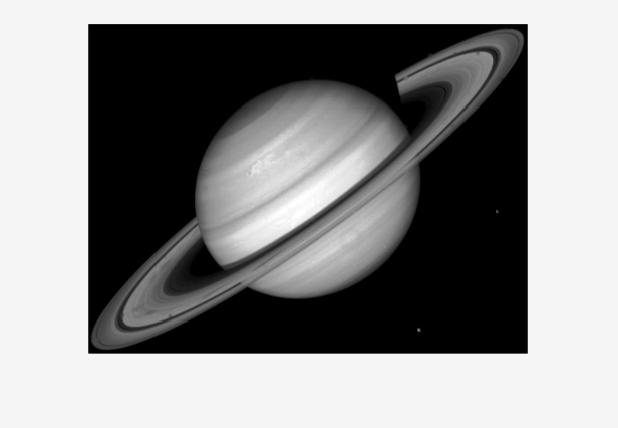

x =    403
    43


y =     29
   295


P =     35    35    35
   128   128   128


clc
clear all;
close all;

% Read original image.
I = imread('saturn.tif');

% Seleccionar dos puntos de los anillos.
% impixel devuelve sus coordenadas x e y.

figure
[x, y, P] = impixel(I)

srcPoints = [x y]

srcPoints =    403    29
    43   295


dstPoints = [100 100; ...
            300 100]; % Posición de los extremos de los anillos para que queden en posición horizontal
[tform,inlierIndex,status] = estgeotform2d(srcPoints, dstPoints,'similarity')  

tform =   simtform2d with properties:

    Dimensionality: 2
             Scale: 0.4468
     RotationAngle: -143.5397
       Translation: [237.1219 217.4290]
                 R: [2×2 double]

                 A: [-0.3594    0.2655  237.1219
                     -0.2655   -0.3594  217.4290
                           0         0    1.0000]


inlierIndex = 2×1 logical array
   1
   1


status = int32
0

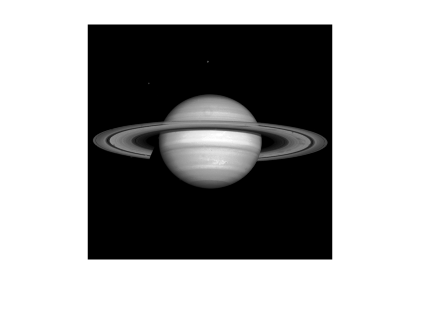

destino = imwarp(I,tform);   % Realiza el inverse warping
figure; imshow(destino);

Modifique los valores de los puntos de destino para que la imagen final quede con orientación distinta y muéstrela.

dstPoints = [100 100; 100 300];
[tform, inlierIndex, status] = estgeotform2d(srcPoints, dstPoints, 'similarity')

tform =   simtform2d with properties:

    Dimensionality: 2
             Scale: 0.4468
     RotationAngle: -53.5397
       Translation: [-17.4290 237.1219]
                 R: [2×2 double]

                 A: [ 0.2655    0.3594  -17.4290
                     -0.3594    0.2655  237.1219
                           0         0    1.0000]


inlierIndex = 2×1 logical array
   1
   1


status = int32
0

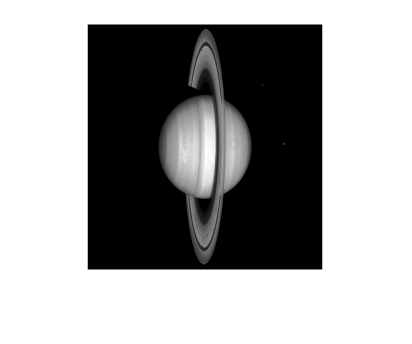

destino2 = imwarp(I, tform);
figure
imshow(destino2);

# Corrección de la Perspectiva con Homografía

Para corregir la perspectiva de un objeto es necesario estimar la transformación de la perspectiva. Cuatro pares de puntos correspondientes son suficientes para recuperar una transformación de perspectiva entre dos imágenes. El objetivo de esta práctica es corregir la perspectiva de la carta de la imagen "card.jpg",

Se pide: 

- Cargue la imagen "`card.jpg`". Haga clic en las cuatro esquinas de la tarjeta para obtener los primeros cuatro puntos utilizando la función `impixel`. Nota: utilice el siguiente orden para obtener los cuatro puntos: 1) Esquina superior izquierda, 2) Esquina superior derecha, 3) Esquina inferior derecha, 4) Esquina inferior izquierda.

- Calcule los cuatro puntos de la carta de póquer sin distorsión de perspectiva, teniendo en cuenta que una carta de póquer tiene un tamaño de 100` mm` por `150 mm` aproximadamente.

- Estime la transformación de la perspectiva utilizando la función `estgeotform2d` sabiendo que en este caso el tipo de transformación es `"``projective``".` 

- Aplicar la transformación de perspectiva utilizando la función `imwarp`.

- Muestre la carta no distorsionada.

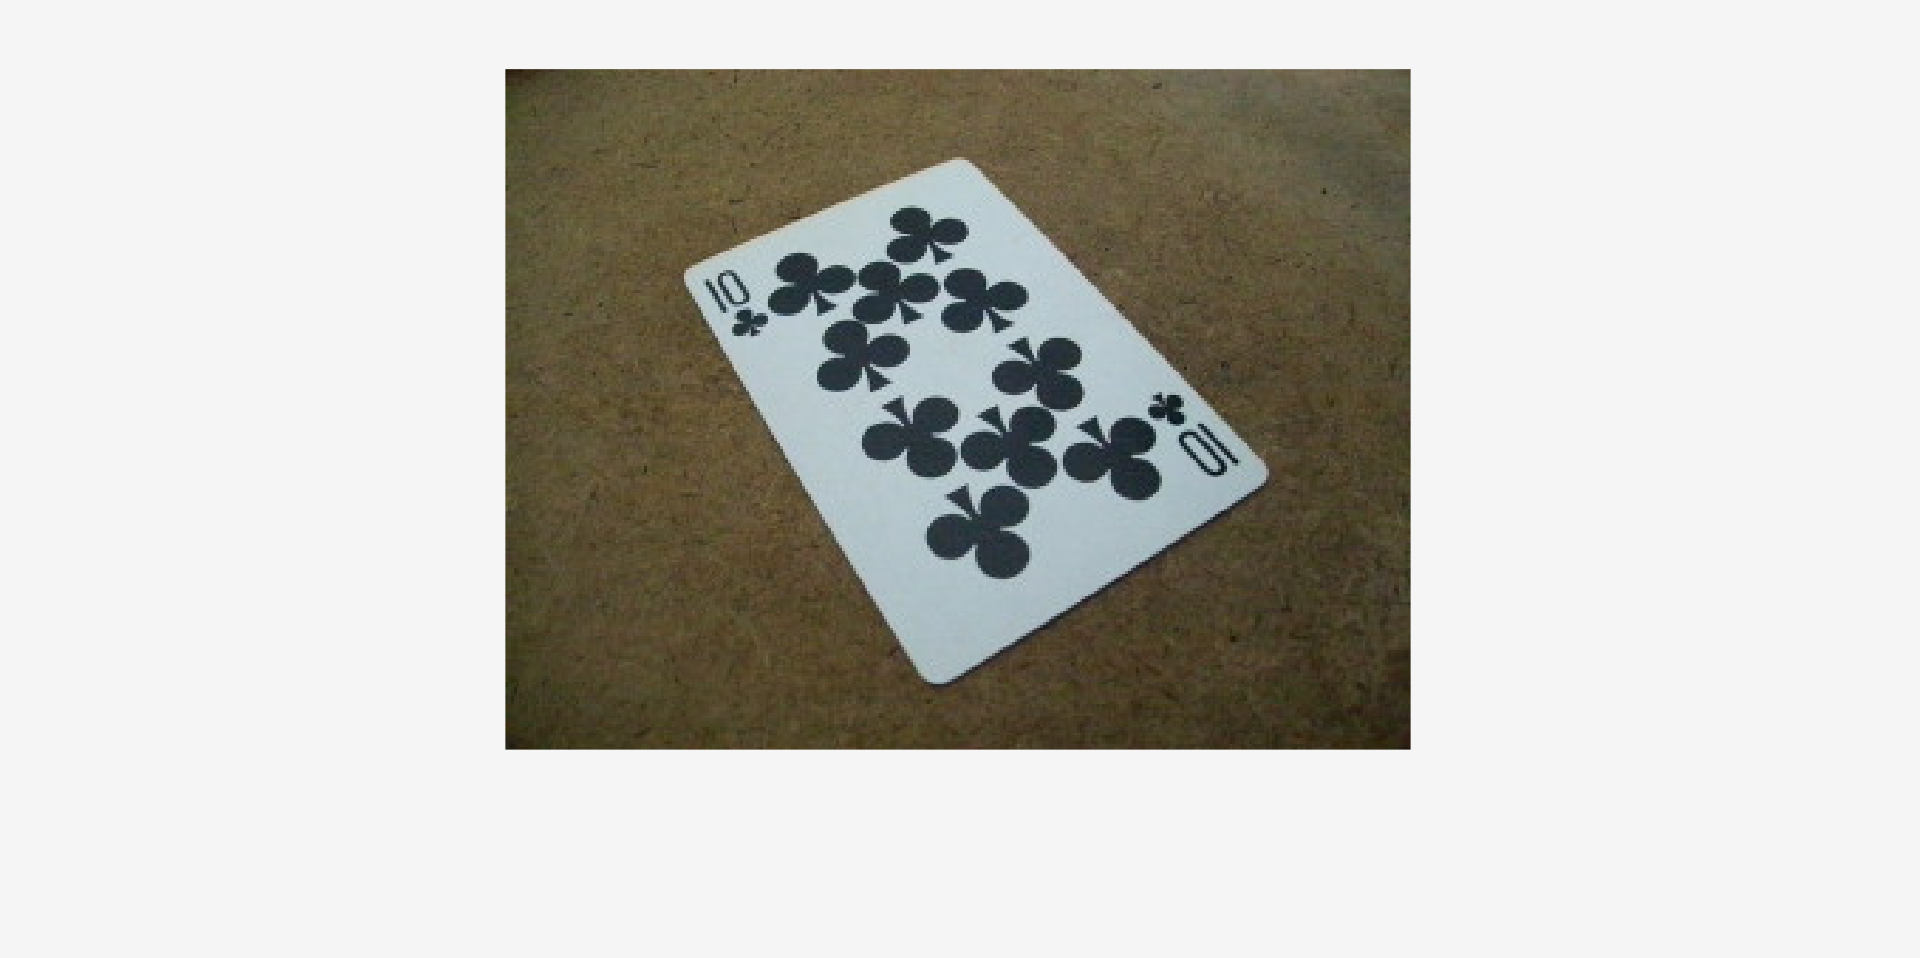

x =     65
   162
   270
   154


y =     72
    32
   142
   216


P =    198   189   180
   158   146   122
   140   136   133
   165   185   192


I2 = imread('card.jpg');
figure
[x, y, P] = impixel(I2)

srcPoints = [x y]

srcPoints =     65    72
   162    32
   270   142
   154   216



dstPoints = [100 100; 400 100; 400 550; 100 550];

[tform, inlierIndex, status] = estgeotform2d(srcPoints, dstPoints, 'projective')

tform =   projtform2d with properties:

    Dimensionality: 2

                 A: [ 2.7151   -1.3478   44.2955
                      1.7569    4.5975 -321.4825
                     -0.0000    0.0033    1.0000]


inlierIndex = 4×1 logical array
   1
   1
   1
   1


status = int32
0

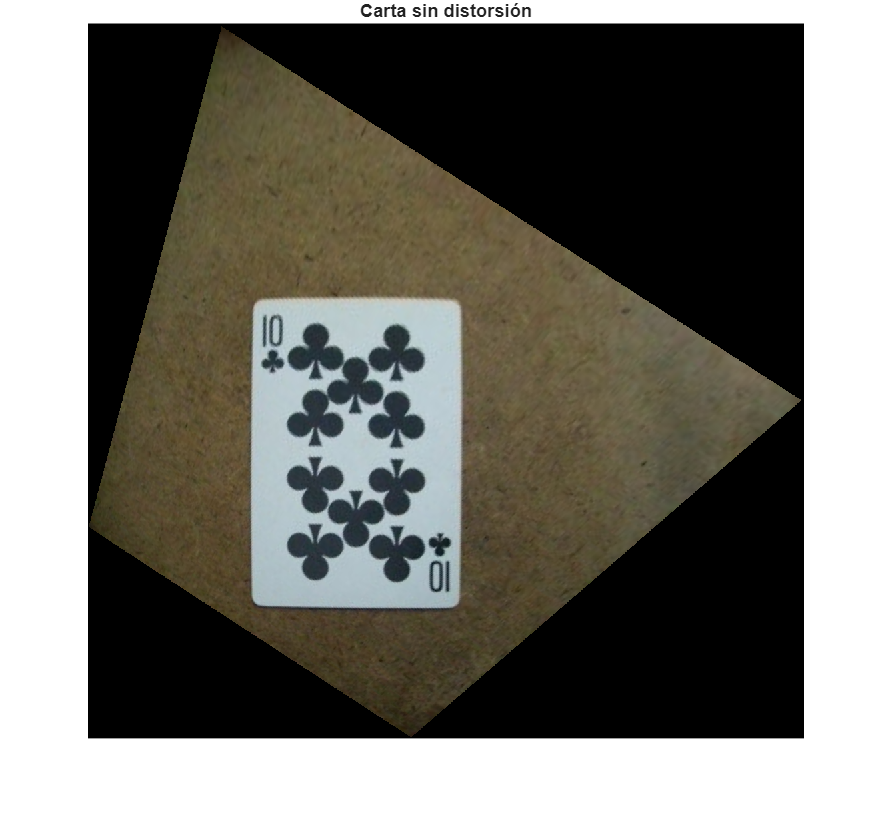


carta = imwarp(I2, tform);

figure
imshow(carta);
title('Carta sin distorsión');